# Gaussian Beam Scattered Off a Sphere

## Simulated a focused Gaussian beam using the Optical Tweezers Toolbox

First we clear all existing variables and configure OTT warnings -- show warning only once and turn off warning related to future OTT function changes.

clear;
ott.warning('once');
ott.change_warnings('off');

Simulation parameters

n_medium = 1.0;         % Vacuum
wavelength0 = 1064e-9;  % Vacuum wavelength (m)

% Numerical aperture of the beam
% Assume a w0 = 7.5 um waist,
% the half opening angle is 
% lim_{z->\infty} arctan(w(z) / z),
% or `theta = lambda / (pi * w0 * n)` 
% in paraxial approx.
% where n = 1 is the index of the medium
% NA = n * sin(theta)
NA = 0.0451;

% Number of beam shape coefs to be used
Nmax = 200;

% Polarization in Jones vector. [ 1 0 ]: linear polarization in x
% [ 0 1 ]: y-polarized. [ 1 -i ] and [ 1 i ] are circularly polarized.
polarisation = [1 0];

% Spatial mode of the incident light in the Laguerre-Gauss
% basis. Fundamental Gaussian profile = [0 0].
lg_mode = [0 0];

beam_offset = [0; 0; 0];

Construct the beam

beam = ott.BscPmGauss('type','lg', 'mode', lg_mode, ...
                      'polarisation', polarisation, 'NA', NA,...
                      'offset', beam_offset, 'index_medium', n_medium, ...
                      'wavelength0', wavelength0, ...
                      'Nmax', Nmax);

% Normalize the beam power before moving forward
beam.power = 1.0;

Construct the beam using Juan's code. This peice of code uses `bsc_pointmatch_farfield.m`, which is a part of a previous release of OTT. We need to check whether the two pieces of code give beams that agree with each other.

beam_angle = asin(NA/n_medium)*180/pi;
w0 = lg_mode_w0( lg_mode, beam_angle );  % Waist in unit of wavelength
offset = [0 0 0];  % Location of focal point w.r.t the particle

% Create the trapping field:
% Use this for focused Gaussian field
[n, m, a0, b0] = bsc_pointmatch_farfield(Nmax, 1, [ lg_mode w0 1 polarisation 90 offset ]);
[a, b, n, m] = make_beam_vector(a0, b0, n, m);

% Normalize total power of wave sum to 1
pwr = sqrt(sum( abs(a).^2 + abs(b).^2 ));
a = a / pwr;
b = b / pwr;

mybeam = ott.Bsc(a, b, 'regular', 'incident');

The beam coefficients do not match for some reason. There is a pi/2 phase shift, i.e., `mybeam.a/mybeam.b` * i = `beam.a/beam.b` between the two sets of beam coefficients. It is unclear to me why there is a discrepency.

mybeam.a

ans =          (1,1)           -0.0000 - 0.0276i
         (3,1)           -0.0000 - 0.0276i
         (5,1)            0.0355 + 0.0000i
         (7,1)            0.0355 + 0.0000i
        (11,1)           -0.0000 + 0.0419i
        (13,1)            0.0000 + 0.0419i
        (19,1)           -0.0473 - 0.0000i
        (21,1)           -0.0473 - 0.0000i
        (29,1)           -0.0000 - 0.0520i
        (31,1)           -0.0000 - 0.0520i
        (41,1)            0.0562 - 0.0000i
        (43,1)            0.0562 + 0.0000i
        (55,1)           -0.0000 + 0.0600i
        (57,1)            0.0000 + 0.0600i
        (71,1)           -0.0633 + 0.0000i
        (73,1)           -0.0633 - 0.0000i
        (89,1)           -0.0000 - 0.0664i
        (91,1)            0.0000 - 0.0664i
       (109,1)            0.0691 + 0.0000i
       (111,1)            0.0691 + 0.0000i
       (131,1)           -0.0000 + 0.0715i
       (133,1)            0.0000 + 0.0715i
       (155,1)           -0.0736 + 0.0000i
     

beam.a

ans =          (1,1)            0.0276 - 0.0000i
         (3,1)            0.0276 + 0.0000i
         (5,1)           -0.0000 + 0.0355i
         (7,1)           -0.0000 + 0.0355i
        (11,1)           -0.0419 + 0.0000i
        (13,1)           -0.0419 + 0.0000i
        (19,1)            0.0000 - 0.0473i
        (21,1)           -0.0000 - 0.0473i
        (29,1)            0.0520 + 0.0000i
        (31,1)            0.0520 + 0.0000i
        (41,1)           -0.0000 + 0.0562i
        (43,1)            0.0000 + 0.0562i
        (55,1)           -0.0600 - 0.0000i
        (57,1)           -0.0600 + 0.0000i
        (71,1)           -0.0000 - 0.0633i
        (73,1)           -0.0000 - 0.0633i
        (89,1)            0.0664 + 0.0000i
        (91,1)            0.0664 + 0.0000i
       (109,1)           -0.0000 + 0.0691i
       (111,1)            0.0000 + 0.0691i
       (131,1)           -0.0715 - 0.0000i
       (133,1)           -0.0715 - 0.0000i
       (155,1)            0.0000 - 0.0736i
     

### Near field behavior of the beam

Calculate the electric field on the focal plane

[xlim, ylim] = deal(5e-5, 5e-5); % meter
[xsize, ysize] = deal(100, 100);

xrange = linspace(-xlim, xlim, xsize);
yrange = linspace(-ylim, ylim, ysize);
[xx, yy, zz] = meshgrid(xrange, yrange, 0);
xyz = [xx(:), yy(:), zz(:)];

beam.basis = 'regular';
[E, ~, ~] = beam.emFieldXyz(xyz.', 'calcE', true, 'calcH', false);

% Ex^2 + Ey^2 + Ez^2
E_square = sum(abs(E.').^2, 2);

% Reshape the output
imout = zeros(xsize, ysize, 1);
imout(:, :, 1) = reshape(E_square, xsize, ysize);

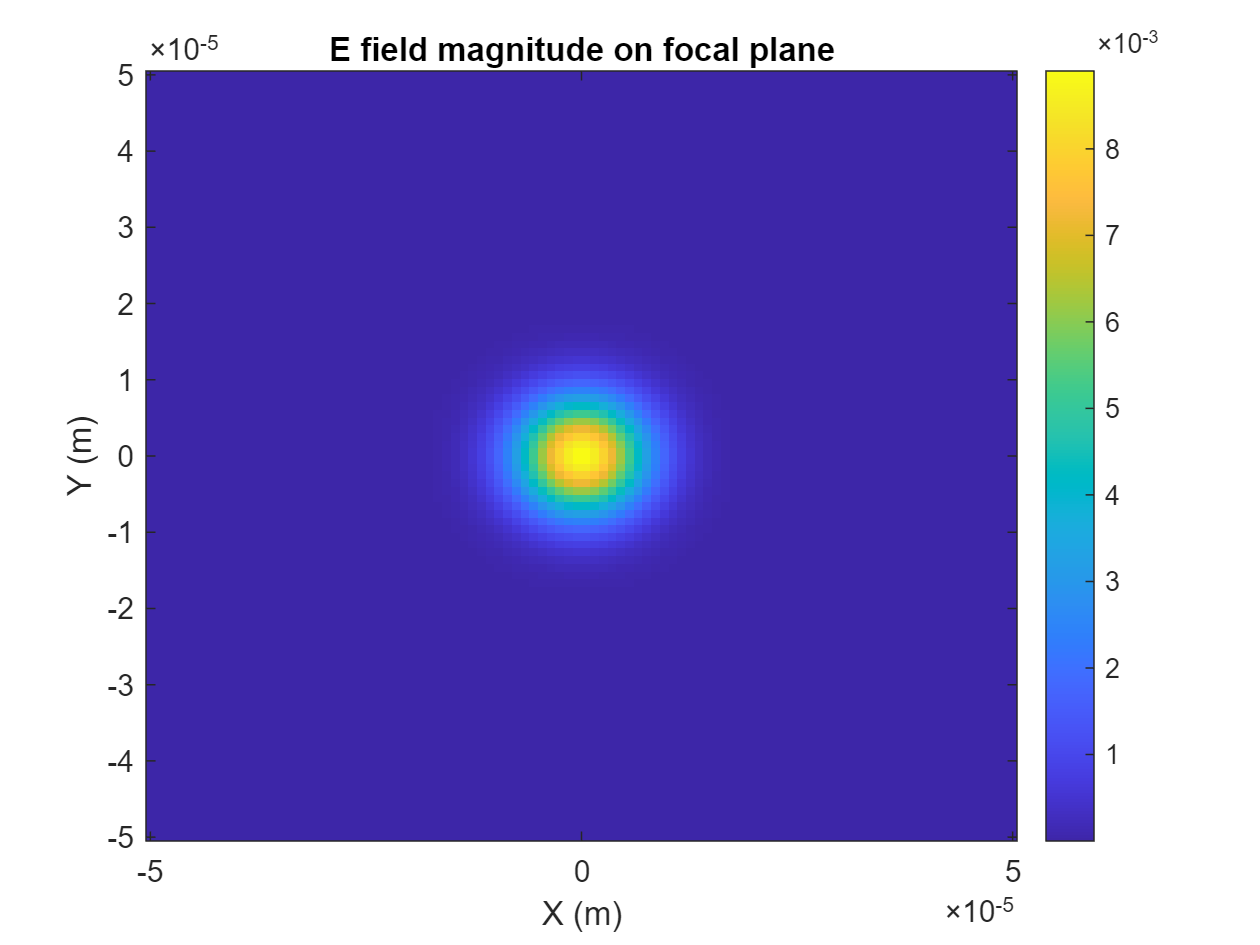

% Need to transpose the image before plotting
% Because the field values are for `xyz.'`
imagesc(xrange, yrange, sqrt(imout.'));

% To have the plot starts at the bottom left corner
axis xy;
colorbar;
title('E field magnitude on focal plane')
xlabel('X (m)')
ylabel('Y (m)')

Calculate E field above the focal plane. The beam is indeed diverging when away from the focal plane.

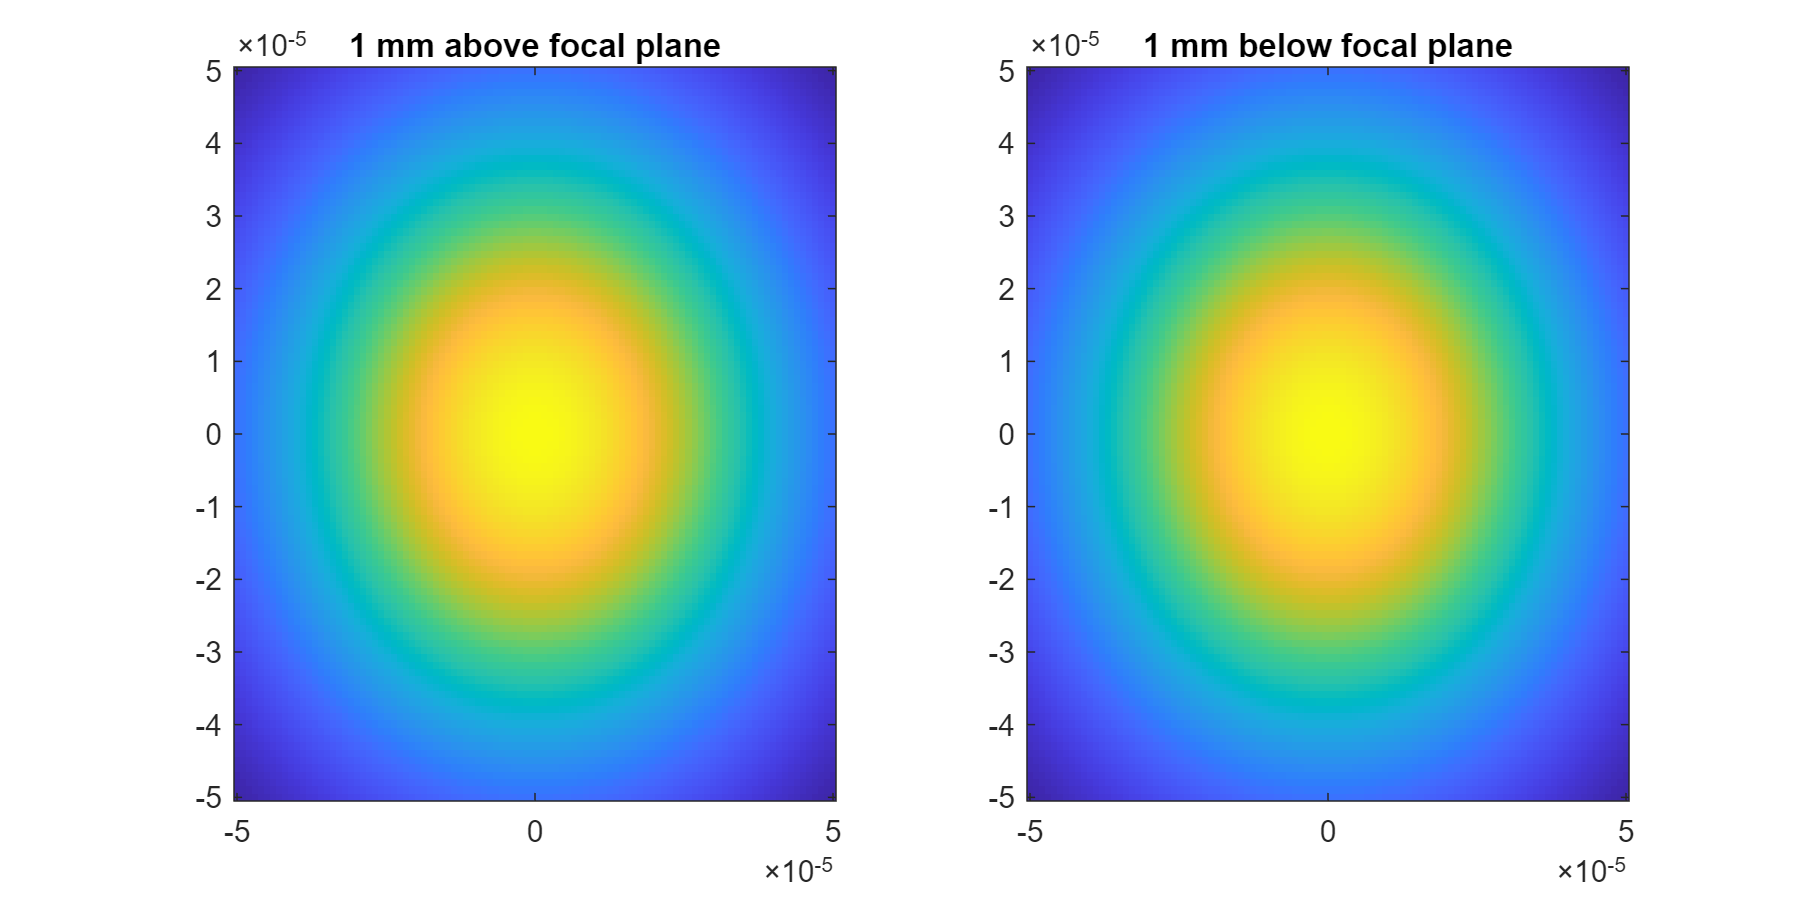

[xx, yy, zz] = meshgrid(xrange, yrange, 1e-3);
xyz = [xx(:), yy(:), zz(:)];

beam.basis = 'regular';
[E, ~, ~] = beam.emFieldXyz(xyz.', 'calcE', true, 'calcH', false);

% Ex^2 + Ey^2 + Ez^2
E_square = sum(abs(E.').^2, 2);

% Reshape the output
imout = zeros(xsize, ysize, 1);
imout(:, :, 1) = reshape(E_square, xsize, ysize);

figure();
set(gcf, 'position', [10, 10, 900, 400]);

subplot(1, 2, 1)
imagesc(xrange, yrange, sqrt(imout.'));
axis xy;
title('1 mm above focal plane')

[xx, yy, zz] = meshgrid(xrange, yrange, -1e-3);
xyz = [xx(:), yy(:), zz(:)];

beam.basis = 'regular';
[E, ~, ~] = beam.emFieldXyz(xyz.', 'calcE', true, 'calcH', false);

% Ex^2 + Ey^2 + Ez^2
E_square = sum(abs(E.').^2, 2);

% Reshape the output
imout = zeros(xsize, ysize, 1);
imout(:, :, 1) = reshape(E_square, xsize, ysize);

subplot(1, 2, 2)
imagesc(xrange, yrange, sqrt(imout.'));
axis xy;
title('1 mm below focal plane')

Calculate E field on a x-z slice

[xlim, zlim] = deal(2.5e-4, 1e-3); % meter
[xsize, zsize] = deal(100, 100);

xrange = linspace(-xlim, xlim, xsize);
zrange = linspace(-zlim, zlim, zsize);
[xx, yy, zz] = meshgrid(xrange, 0, zrange);
xyz = [xx(:), yy(:), zz(:)];

beam.basis = 'regular';
[E, ~, ~] = beam.emFieldXyz(xyz.', 'calcE', true, 'calcH', false);

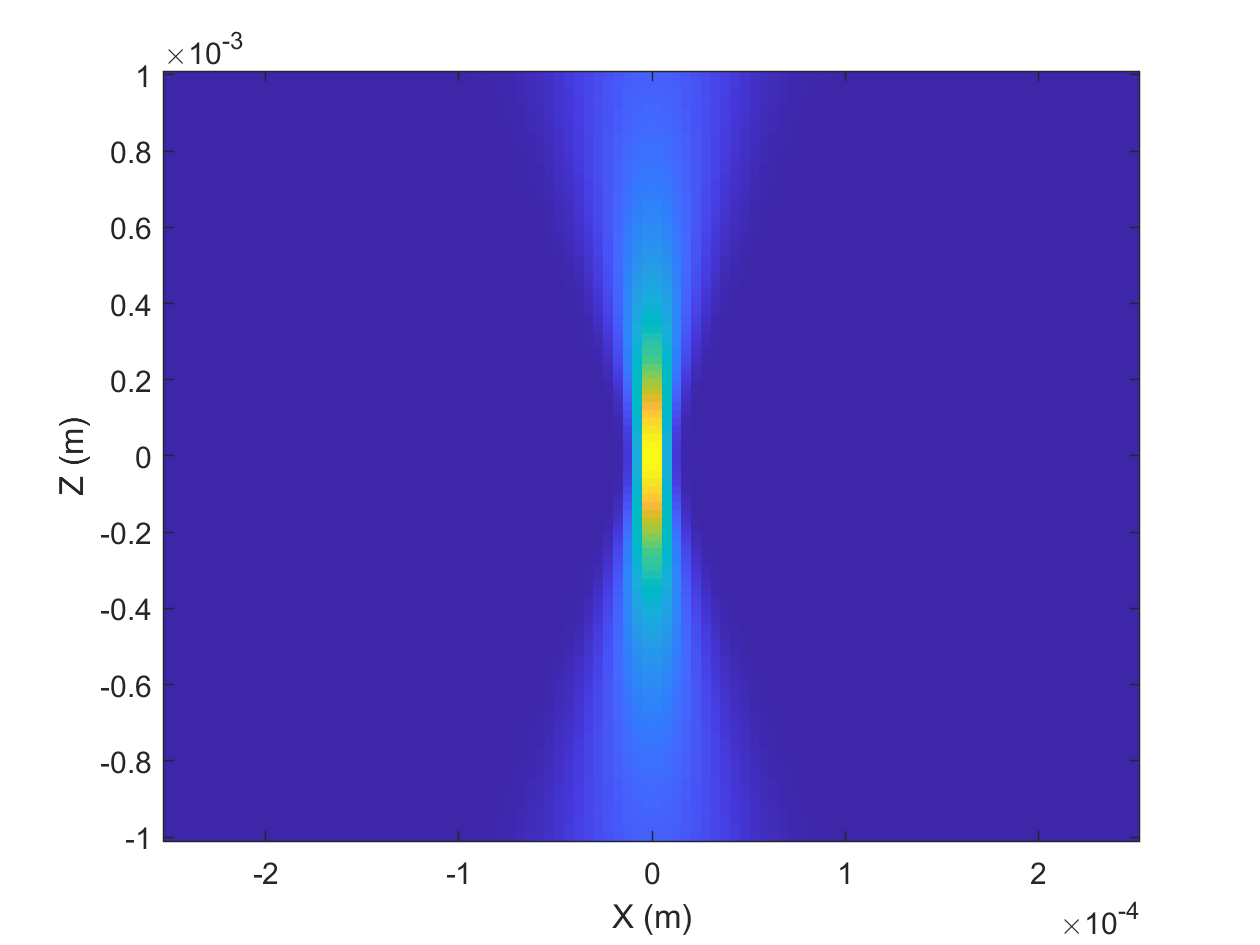

% Ex^2 + Ey^2 + Ez^2
E_square = sum(abs(E.').^2, 2);

% Reshape the output
imout = zeros(xsize, zsize);
imout(:, :) = reshape(E_square, xsize, zsize);

figure()
imagesc(xrange, zrange, sqrt(imout.'));
axis xy;
xlabel('X (m)')
ylabel('Z (m)')

**## Juan's beam on focal plane (the result doesn't make sense -- need to check further, could be due to the OTT upgrade)**

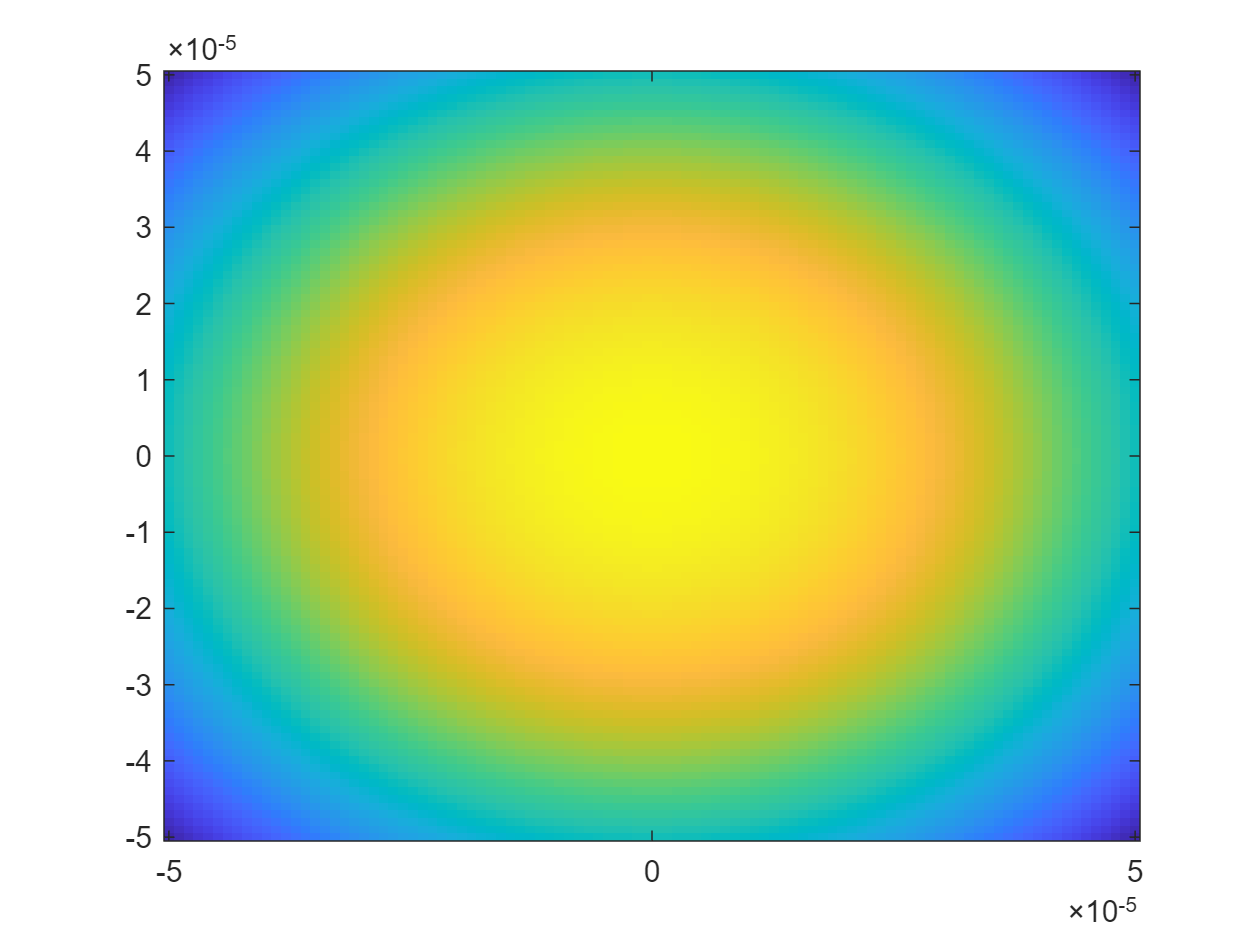

[xlim, ylim] = deal(5e-5, 5e-5); % meter
[xsize, ysize] = deal(100, 100);

xrange = linspace(-xlim, xlim, xsize);
yrange = linspace(-ylim, ylim, ysize);
[xx, yy, zz] = meshgrid(xrange, yrange, 0);
xyz = [xx(:), yy(:), zz(:)];

mybeam.basis = 'regular';
[E_, ~, ~] = mybeam.emFieldXyz(xyz.', 'calcE', true, 'calcH', false);

% Ex^2 + Ey^2 + Ez^2
E_square = sum(abs(E_.').^2, 2);

% Reshape the output
imout = zeros(xsize, ysize, 1);
imout(:, :, 1) = reshape(E_square, xsize, ysize);

imagesc(xrange, yrange, sqrt(imout.'));
axis xy;

Use the built-in `visualise` function

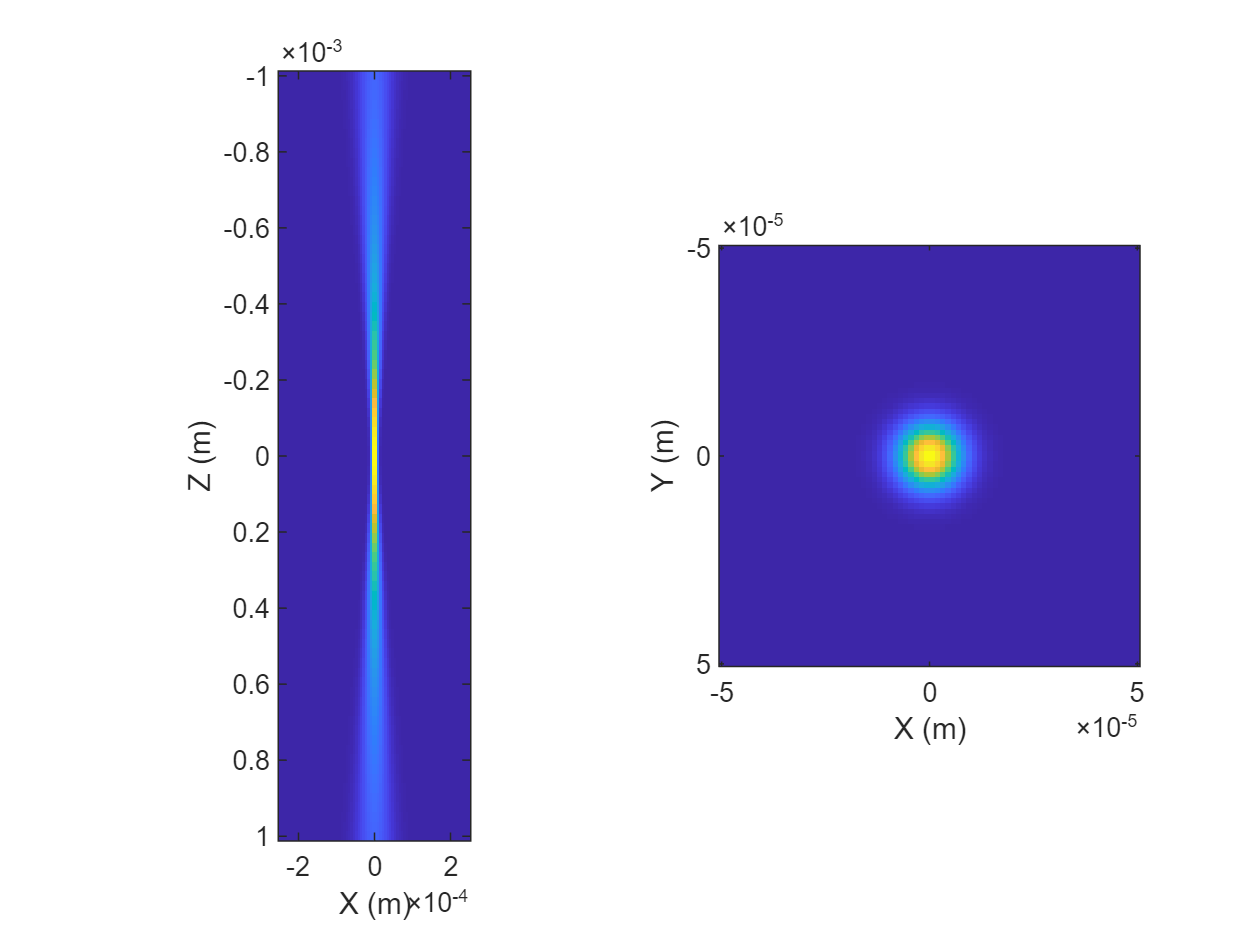

% Near field
% Vector spherical wave function might not be a good approximation
% for the x-z shape (Rayleigh range = 6.64e-4 m)
figure();
beam.basis = 'regular';
subplot(1, 2, 1);
beam.visualise('axis', {[1 0 0], [0 0 1]}, 'range', [2.5e-4, 1e-3]);
xlabel('X (m)');
ylabel('Z (m)');
beam.basis = 'regular';
radius = 5e-6;
subplot(1, 2, 2);
beam.visualise('axis', 'z', 'range', [5e-5, 5e-5]); %, 'mask', @(xyz) vecnorm(xyz) < radius);
xlabel('X (m)')
ylabel('Y (m)')

### Far field behavior of the beam

[xlim, ylim] = deal(0.2, 0.2); % meter
[xsize, ysize] = deal(100, 100);

% X, Y coordinates in the far field
xrange = linspace(-1, 1, xsize) * xlim;
yrange = linspace(-1, 1, ysize) * ylim;
[xx, yy] = meshgrid(xrange, yrange);

% Convert `xx` and `yy` into spherical coords
phi = atan2(yy, xx);
rr = sqrt(xx.^2 + yy.^2);

% Assume 1 m away from the center
theta = asin(rr);

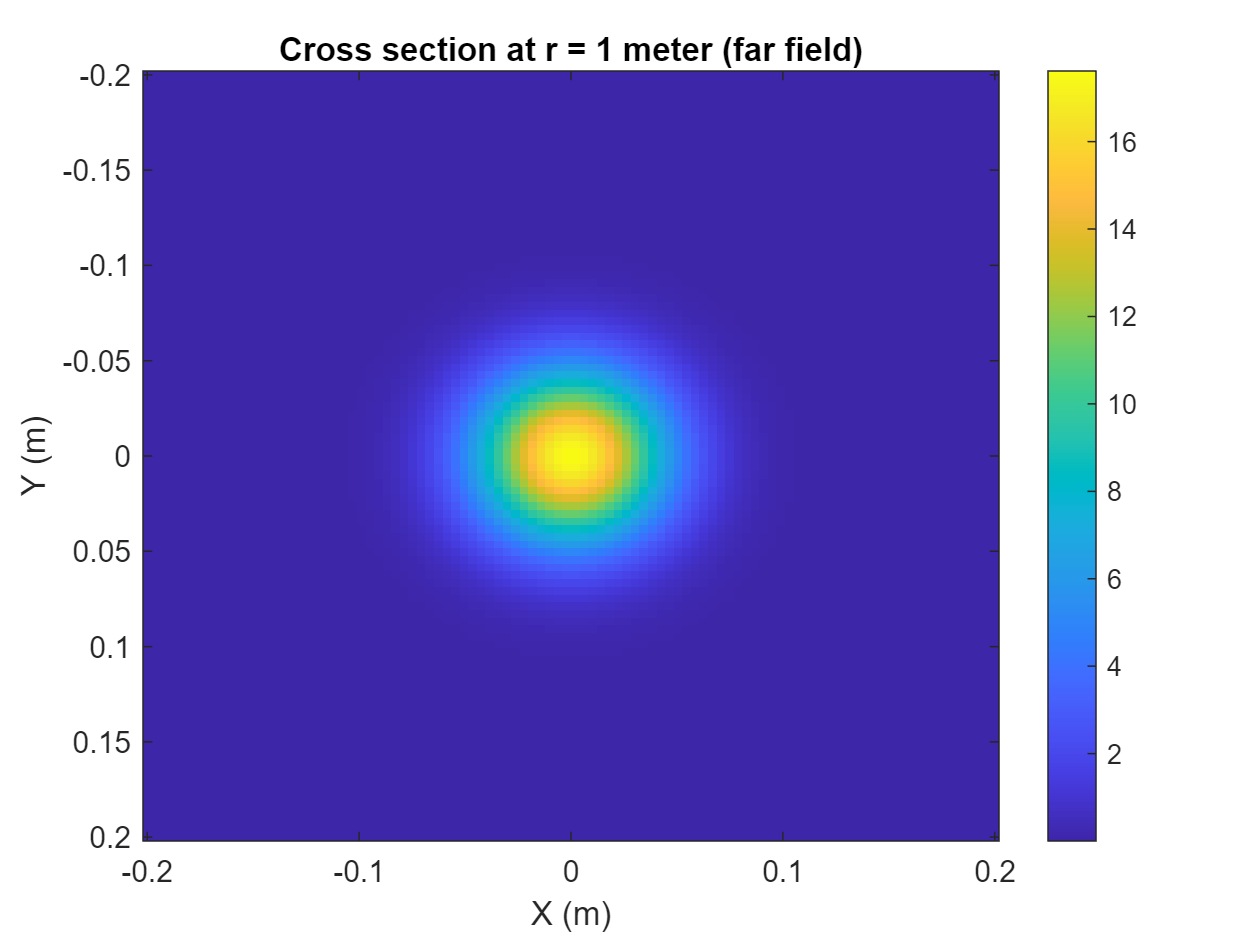

% Should use 'outgoing' basis function
% because the theta-phi coords are w.r.t the center
% See https://www.sciencedirect.com/science/article/pii/S0022407302003369
% for descriptions of the basis

% This paper gives an analytic formula for Gaussian beam in the far field
% https://opg.optica.org/abstract.cfm?URI=josa-69-5-761
% which seems to agree with what we get here
beam.basis = 'outgoing';
[outputE, ~, ~] = beam.farfield(theta(:), phi(:), 'calcE', true, 'calcH', false);
E_square = sum(abs(outputE.').^2, 2);
imout = zeros(xsize, zsize);
imout(:, :) = reshape(E_square, xsize, zsize);

figure();
imagesc(xrange, yrange, sqrt(imout))
title('Cross section at r = 1 meter (far field)')
colorbar
xlabel('X (m)')
ylabel('Y (m)')

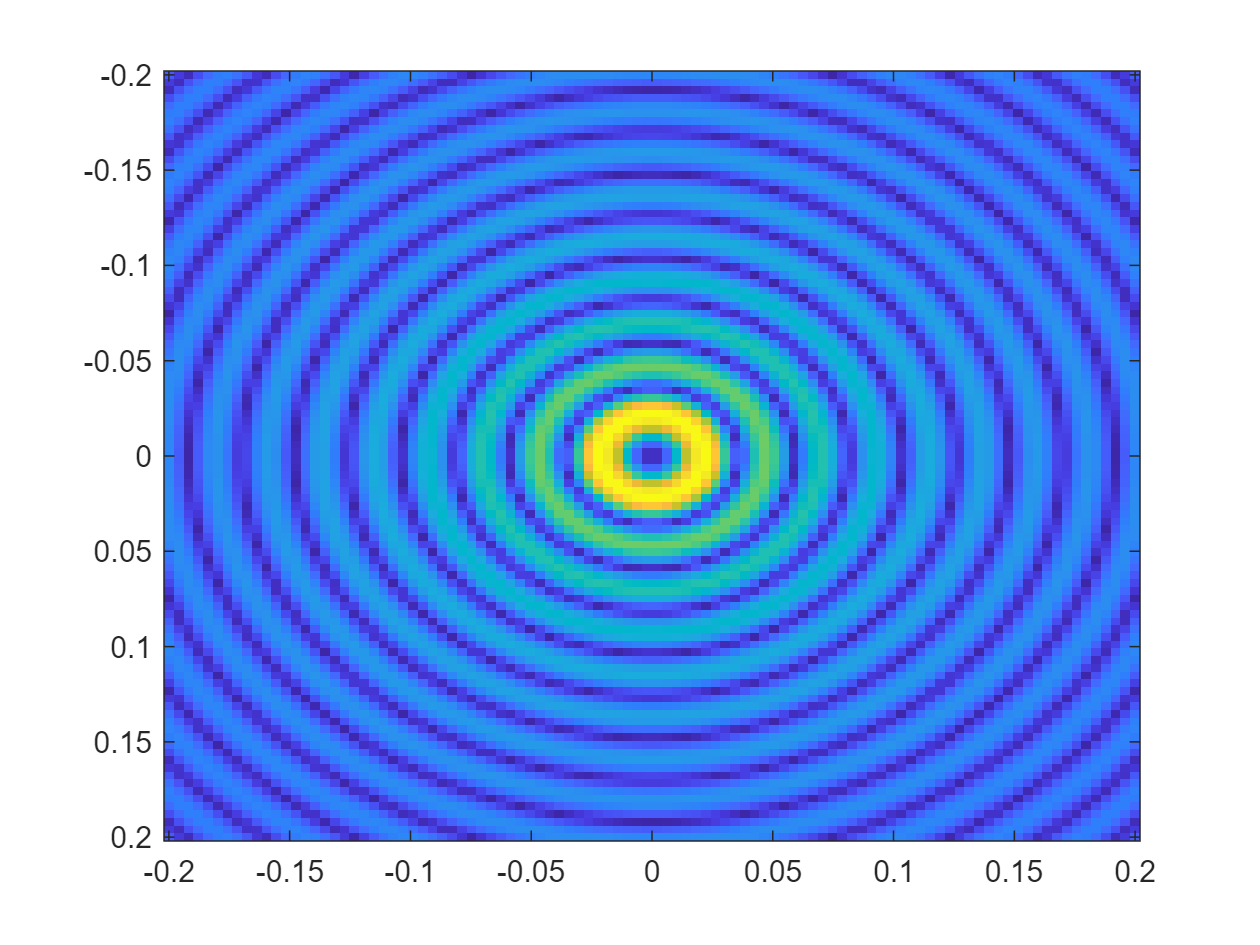

% Will see something strange if we use the wrong basis
beam.basis = 'incoming';
[outputE, ~, ~] = beam.farfield(theta(:), phi(:), 'calcE', true, 'calcH', false);
E_square = sum(abs(outputE.').^2, 2);
imout = zeros(xsize, zsize);
imout(:, :) = reshape(E_square, xsize, zsize);
imagesc(xrange, yrange, sqrt(imout))

Use the built-in `visualiseFarfield` function 

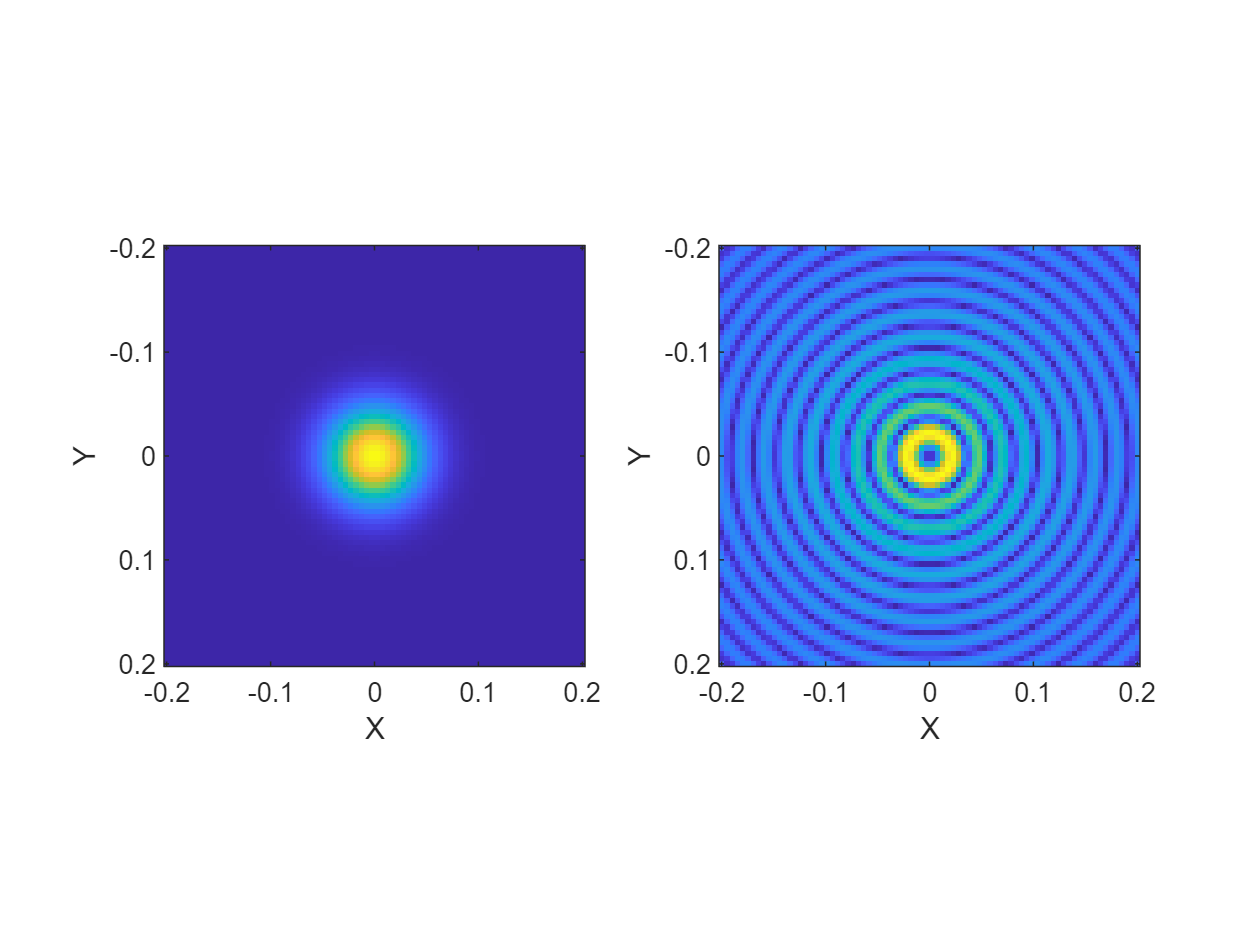

% Far field visualization
beam.basis = 'outgoing';

figure();
subplot(1, 2, 1);
beam.visualiseFarfield('dir', 'pos', 'range', [0.2, 0.2]);

% The other half of the beam, but still in the
% 'outgoing' (incorrect) basis
subplot(1, 2, 2)
beam.visualiseFarfield('dir', 'neg', 'range', [0.2, 0.2]);

Calculate the T-matrix

n_particle = 1.5;
radius = 5e-6;
T = ott.Tmatrix.simple('sphere', radius, 'wavelength0', wavelength0, ...
   'index_medium', n_medium, 'index_particle', n_particle, 'Nmax', Nmax);

T

sbeam = T * beam;

sbeam

Scattered and total field around the beam focus

figure();
subplot(1, 2, 1);
sbeam.basis = 'regular';
sbeam.visualise('axis', 'z', 'field', 'irradiance',...
   'mask', @(xyz) vecnorm(xyz) < radius, 'range', [20,20]*2e-6)
title('Scattered field');

subplot(1, 2, 2);
tbeam = sbeam.totalField(beam);
tbeam.basis = 'regular';
tbeam.visualise('axis', 'z', 'field', 'irradiance',...
   'mask', @(xyz) vecnorm(xyz) < radius, 'range', [20,20]*2e-6)
title('Total field');
tbeam

Far-field pattern of the total beam

tbeam.basis = 'incoming';

figure();
tbeam.visualiseFarfield('dir', 'neg');

beam.set_Nmax(250);
beam.basis = 'incoming';

figure();
beam.visualiseFarfield('dir', [0 0]);


% Calculate the force along z
wavelength_medium = wavelength0/n_medium;
z = [0;0;1] * linspace(-30, 30, 100) * wavelength_medium;
fz = ott.forcetorque(beam, T, 'position', z);

% Generate a plot
figure();
plot(z(3, :)/wavelength_medium,fz(3, :));
xlabel('{\it z} [\lambda_m]');
ylabel('{\it Q_z} [n_m P / c]');
aa = axis;
hold on;
line(aa(1:2),[ 0 0 ],'linestyle',':');
line([0 0],aa(3:4),'linestyle',':');
hold off;